## Interpolate sine data

ws = logspace(.7,2,20)

ws =     5.0119    5.8671    6.8682    8.0401    9.4120   11.0181   12.8981   15.0990   17.6754   20.6914   24.2220   28.3551   33.1935   38.8574   45.4878   53.2495   62.3357   72.9723   85.4238  100.0000


indx = 20;

w = ws(indx);
fileName = sprintf("./pd_freq_response/freq_response_%d.mat",indx)

fileName = "./pd_freq_response/freq_response_20.mat"


load(fileName);


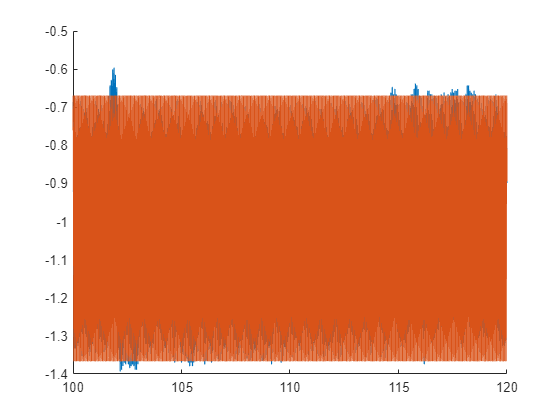

figure();
hold on;
plot(x_res.time,x_res.signals.values);

sinDta = interpolateSineData(x_res.time,x_res.signals.values,w);

interpolatedSine = sinDta.U*sin(w*x_res.time+sinDta.Phi)+sinDta.M;

plot(x_res.time,interpolatedSine);

## Plotting response


U_data = zeros(length(ws),3);
for i = 1:length(ws)
    w_i = ws(i);
    file_i = sprintf("./pd_freq_response/freq_response_%d.mat",i);

    load(file_i);

    sinDta = interpolateSineData(x_res.time,x_res.signals.values,w_i);

    U_data(i,1) = ws(i); U_data(i,2) = 20*log10(abs(sineData.U)/U_in); U_data(i,3) = rad2deg(sineData.Phi);

end

load("pd_parameters.mat");
%ws = logspace(-3,3);
j = sqrt(-1);
U_data

U_data =     5.0119  -11.1107 -150.1104
    5.8671  -11.0830 -150.1104
    6.8682  -11.0455 -150.1104
    8.0401  -10.9949 -150.1104
    9.4120  -10.9269 -150.1104
   11.0181  -10.8364 -150.1104
   12.8981  -10.7170 -150.1104
   15.0990  -10.5614 -150.1104
   17.6754  -10.3618 -150.1104
   20.6914  -10.1109 -150.1104


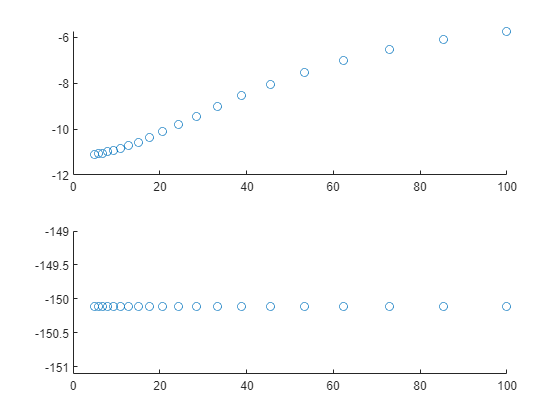

figure();
subplot(2,1,1)
hold on;
% %loglog(U_data(:,1),U_data(:,2),'o')\
% for i = length(ws)
%     Us(i) = 20*log10(abs(G_jw(ws(i))));
% end
semilogx(ws,U_data(:,2),'o');

subplot(2,1,2)
hold on;
semilogx(ws,U_data(:,3),'o');

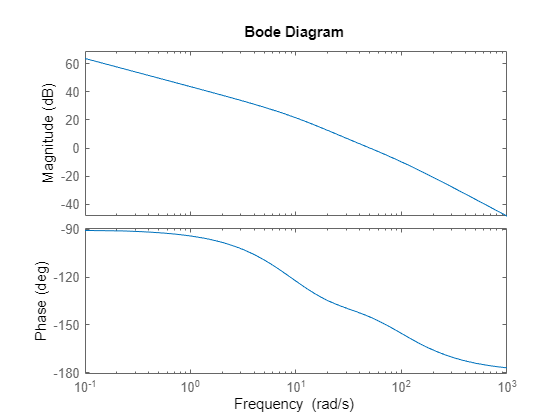

figure();
s = tf("s");
G_s = (pd_param.Kp + pd_param.Kd*(pd_param.a*s)/(s+pd_param.a))*(1/(m*s^2 + b*s));
bode(G_s)

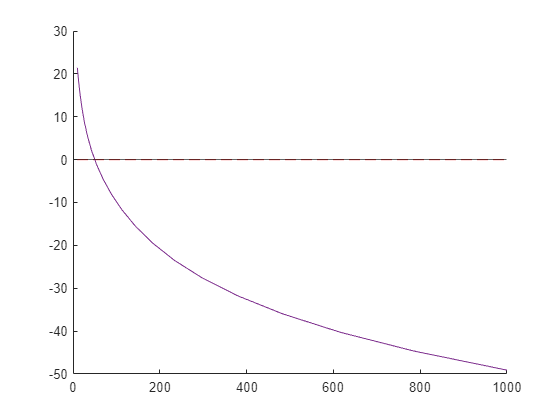

% ows = logspace(1,3,20);
% %G_jw = @(w) (pd_param.Kp + pd_param.Kd*(pd_param.a*j*w)/(j*w + pd_param.a))*(1/(m*(j*w)^2 + b*(j*w)));
% P_jw = @(w) pd_param.Kp + pd_param.Kd * (pd_param.a*j*w)/(j*w + pd_param.a);
% G_jw = @(w) 1/(j*w*(j*w*m + b));
% L_jw = @(w) P_jw(w) * G_jw(w);
% Us = zeros(length(ows),1);
% for i = length(ows)
%     w_i = ows(i);
%     Us(i) = 20*log10(abs(L_jw(w_i)))
% end
j = sqrt(-1);
Gs =@(s) (pd_param.Kp + pd_param.Kd*(pd_param.a*s)/(s+pd_param.a))*(1/(m*s^2 + b*s));
G_jw = @(w) Gs(j*w);

ows = logspace(1,3,20);
% %G_jw = @(w) (pd_param.Kp + pd_param.Kd*(pd_param.a*j*w)/(j*w + pd_param.a))*(1/(m*(j*w)^2 + b*(j*w)));
% P_jw = @(w) pd_param.Kp + pd_param.Kd * (pd_param.a*j*w)/(j*w + pd_param.a);
% G_jw = @(w) 1/(j*w*(j*w*m + b));
% L_jw = @(w) P_jw(w) * G_jw(w);
Us = zeros(length(ows),1);
for i = length(ows)
    w_i = ows(i);
    Us(i) = 20*log10(abs(G_jw(w_i)));
end

ows = logspace(1,3,20);
t = 0:0.001:200;
Us = zeros(length(ows),3);
for i = 1:length(ows)
    w_i = ows(i);

    s_i = sin(ows(i)*t);
    ys = lsim(G_s,s_i,t);

    t_mask = t>20;

    sinDta = interpolateSineData(t(t_mask)',ys(t_mask),w_i);
    U(i,1) = w_i; U(i,2) = 20*log10(sinDta.U); U(i,3) = sinDta.Phi;
end

figure();
hold on;
semilogx(ows',Us,'r--')
semilogx(U(:,1),U(:,2))
yline(0)